# Uniform sampling of E. coli core via Riemannian Hamiltonain Monte Carlo (RHMC)

## Author(s): Yunbum Kook (Georgia Tech), Yin Tat Lee (University of Washington), Ruoqi Shen (University of Washington), Santosh Vempala (Georgia Tech)

## Reviewer(s): 

## INTRODUCTION

The flux space $\Omega$ for a given set of biochemical and physiologic constraints is represented by: 


$$\Omega = \{v \mid Sv=b; l \leq v\leq u\}$$


where $v$ represents feasible flux vectors,  $S\in\mathcal{Z}^{m\times n}$ the stoichiometric matrix, while $l$ and $u$ are lower and upper bounds on fluxes. These criteria still allow a wide range of admissible flux distributions which, in FBA are commonly further restricted by introducing an objective to optimise, transforming the question of admissible fluxes into an FBA problem${\;}^1$ of the form


$$\begin{array}{ll}
\min\limits _{v} & c^{T}v\\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,
\end{array}$$


where $c$ is a linear biological objective function (biomass, ATP consumption, HEME production, etc.). Even under these conditions there is commonly a range of optimal flux distributions, which can be investigated using flux variability analysis. If the general capabilities of the model are of interest, however, uniform sampling of the entire flux space $\Omega$ is able to provide an unbiased characterization, and therefore, can be used to investigate the biochemical networks. It requires collecting a statistically meaningful number of flux distributions uniformly spread throughout the whole flux space and then analysing their properties. There are three basic steps to perform a uniform sampling for a set of feasible fluxes:

- Define the flux space to be sampled from physical and biochemical constraints

- Randomly sample the defined flux space based on uniform statistical criteria

- If is necessary, section the flux space according to post-sampling.

In this tutorial, we introduce how to run a new sampling scheme called Riemannian Hamiltonian Monte Carlo (RHMC) for uniform sampling from the flux space. This algorithm first preprocesses the flux space and then performs a  uniform sampling based on RHMC. Especially for large-size instances, you can find a significant speed-up in sampling compared to the default sampling algorithm, hit-and-run with rounding (CHRR). First of all, the preprocessing part in RHMC is numerically more stable and finishes in one minute even for an instance with 100000 reactions, whereas the preprocessing basd on John's ellipsoid in CHRR takes super-linear time in dimensions of instances. Next, the sampling procedure iteself in RHMC is substantially faster than the random walk based on hit-and-run in CHRR, since the random walk based on RHMC extremely mixes well compared to CHRR.

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

Please note that some of the plotting options in the tutorial require Matlab 2016a or higher. Moreover, the tutorial requires a working installation of the Parallel Computing Toolbox.

% uncomment this line below to see what toolboxes are installed
% ver

In this tutorial, we will perform FVA using the function `fluxVariability`. Change the variable `options.useFastFVA = 1` to use `fastFVA `instead`.` Note that the solver ibm_cplex is required for the function fastFVA.

options.useFastFVA = 0;

## PROCEDURE

## Load E. coli core model

The most appropriate way to load a model into The COBRA Toolbox is to use the `readCbModel` function. 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
    modelOri = readCbModel(fileName);
end
%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

## E. coli core in aerobic an anaerobic conditions

Remove the objective from the model and set a small lower bound on the rate of the biomass reaction

biomassRxnAbbr = 'Biomass_Ecoli_core_N(w/GAM)-Nmet2';
ibm = find(ismember(model.rxns, biomassRxnAbbr));  % column index of the biomass reaction
model.lb(ibm)=0.05;
model.c(:)=0;

We will investigate ATP energy production with limited and unlimited oxygen uptake. 

aerobicModel = changeRxnBounds(model,'EX_o2(e)',-17,'l');
anAerobicModel = changeRxnBounds(model,'EX_o2(e)',-1,'l');

## Flux variability analysis

**I comment out this section, since `fluxVariability` seems to have some error now. You may just skip this section and move onto the next section to learn how to run RHMC.

Flux variability analysis (FVA) returns the minimum and maximum possible flux through every reaction in a model.

% if options.useFastFVA
%     [minUn, maxUn] = fastFVA(aerobicModel, 100);
%     [minLim, maxLim] = fastFVA(anAerobicModel, 100);
% else
%     [minUn, maxUn] = fluxVariability(aerobicModel);
%     [minLim, maxLim] = fluxVariability(anAerobicModel);
% end

% fprintf('Max. biomass production with oxygen uptake: %.4f/h.\n', maxUn(ibm));
% fprintf('Max. biomass production without oxygen uptake: %.4f/h.\n\n', maxLim(ibm));

An overall comparison of the FVA results can be obtained by computing the [Jaccard index](https://en.wikipedia.org/wiki/Jaccard_index) for each reaction. The Jaccard index is here defined as the ratio between the intersection and union of the flux ranges in the aerobic and anaerobic models. A Jaccard index of 0 indicates completely disjoint flux ranges and a Jaccard index of 1 indicates completely overlapping flux ranges. The mean Jaccard index gives an indication of the overall similarity between the models.

% J = fvaJaccardIndex([minUn, minLim], [maxUn, maxLim]);
% fprintf('Mean Jaccard index = %.4f.\n', mean(J));

To visualise the FVA results, we plot the flux ranges as errorbars, with reactions sorted by the Jaccard index.

% E = [(maxUn - minUn)/2 (maxLim - minLim)/2];
% Y = [minUn minLim] + E;
% X = [(1:length(Y)) - 0.1; (1:length(Y)) + 0.1]';
% 
% [~, xj] = sort(J);
% 
% f1 = figure;
% if strcmp(version('-release'), '2016b')
%     errorbar(X, Y(xj, :), E(xj, :), 'linestyle', 'none', 'linewidth', 2, 'capsize', 0);
% else
%     %errorbar(X, Y(xj, :), E(xj, :), 'linestyle', 'none', 'linewidth', 2);
%     hold on
%     errorbar(X(:,1), Y(xj, 1), E(xj, 1), 'linestyle', 'none', 'linewidth', 2,'Color','b');
%     errorbar(X(:,2), Y(xj, 2), E(xj, 2), 'linestyle', 'none', 'linewidth', 2,'Color','r');
% end
% set(gca, 'xlim', [0, length(Y) + 1])
% 
% xlabel('Reaction')
% ylabel('Flux range (mmol/gDW/h)')
% ylim([-50,50])
% yyaxis right
% plot(J(xj),'linewidth', 2)
% legend('Aerobic', 'Anaerobic', 'Jaccard','location', 'northoutside', ...
%        'orientation', 'horizontal')
% ylabel('Jaccard index')

## Sampling

RHMC can be called via the function `sampleCbModel`. The main inputs to `sampleCbModel` are a COBRA model structure, the name of the selected sampler, and a parameter struct that controls properties of the sampler used. In the instance of RHMC, the time limit for sampling (`maxTime)` and the number of samples (`nPointsReturned)` are the only parameters you need to set, since other parameters for RHMC are automatically set in the algorithm. Then you obtain as many statistically independent samples as you requested when running the algorithm. If the running time of RHMC passes the time limit, then it will terminate and return independent samples drawn during the time limit. 

options.nPointsReturned = 1000;
options.maxTime = 3600; % 1hr
[~, X1_un] = sampleCbModel(aerobicModel, [], 'RHMC', options);

  Time spent |    Time left |                  Progress |   Est Samples |  AccProb | StepSize |  MixTime
00d:00:00:15 | 00d:00:00:00 | ######################### |  1064 /  1000 | 0.953233 | 0.200000 |     26.1
Done!


[~, X1_lim] = sampleCbModel(anAerobicModel, [], 'RHMC', options);

  Time spent |    Time left |                  Progress |   Est Samples |  AccProb | StepSize |  MixTime
00d:00:00:16 | 00d:00:00:00 | ######################### |  1206 /  1000 | 0.959644 | 0.181818 |     25.2
Done!


The sampler outputs the sampled flux distributions (X_un and X_lim). 

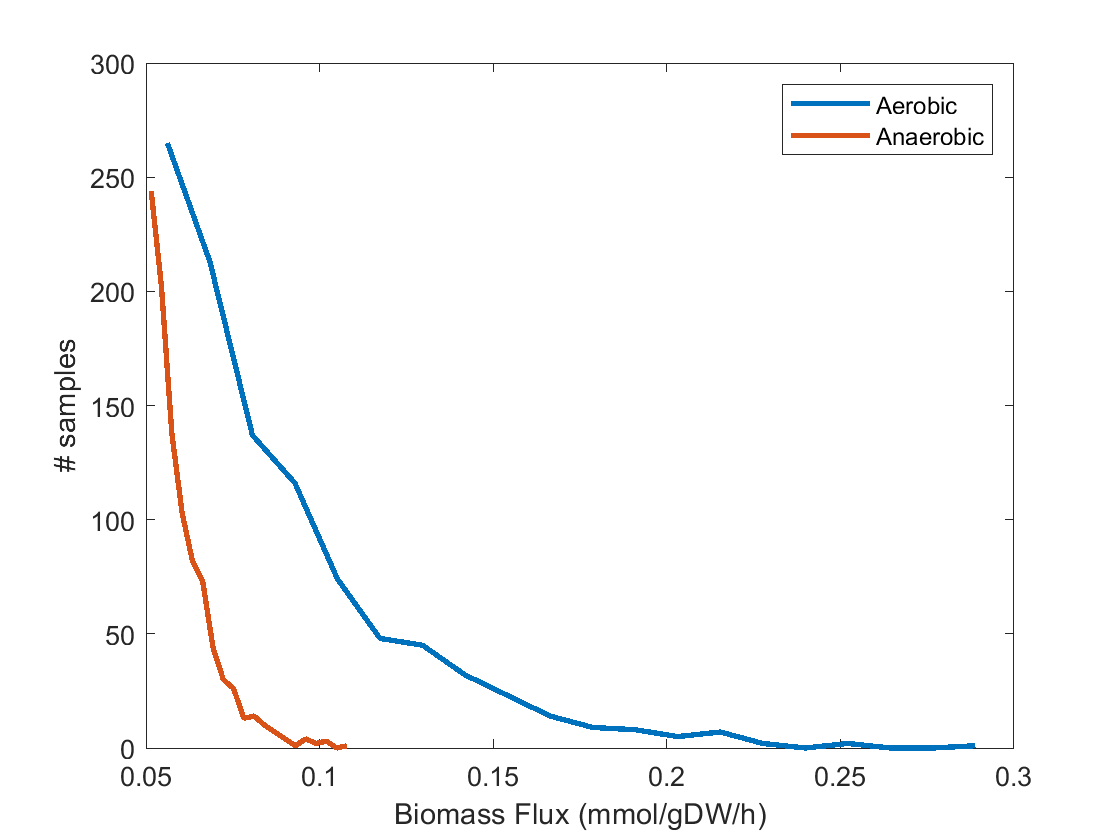

nbins = 20;
[yUn, xUn] = hist(X1_un(ibm, :), nbins,'linewidth', 2);
[yLims, xLims] = hist(X1_lim(ibm, :), nbins,'linewidth', 2);

f3 = figure;
p1 = plot(xUn, yUn, xLims, yLims,'linewidth', 2);
legend('Aerobic', 'Anaerobic')
xlabel('Biomass Flux (mmol/gDW/h)')
ylabel('# samples')

Adding the FVA results to the plot shows that the sampling distributions give more detailed information about the differences between the two models. In particular, we see that the biomass flux minima and maxima are not equally probable. The number of samples from both the aerobic and anaerobic models peaks at the minimum flux of zero, and decreases approximately monotonically towards the maximum growth rate. It decreases more slowly in the unanaerobic model, indicating that higher ATP production is more probable under unlimited oxygen uptake conditions. It is interesting to see that maximum ATP production is highly improbable in both models.

% ylims = get(gca, 'ylim');
% cUn = get(p1(1), 'color');
% cLim = get(p1(2), 'color');
% 
% hold on
% p2 = plot([minUn(ibm), minUn(ibm)], ylims, '--', [maxUn(ibm), maxUn(ibm)], ylims, '--','linewidth', 2);
% set(p2,'color', cUn)
% p3 = plot([minLim(ibm), minLim(ibm)], ylims, '--', [maxLim(ibm), maxLim(ibm)], ylims, '--','linewidth', 2);
% set(p3, 'color', cLim)
% legend('Aerobic', 'Anaerobic', 'AerobicFVA','AerobicFVA', 'AnaerobicFVA','AnaerobicFVA')
% hold off

## Acknowledgements

Based on a ecoli core sampling tutorial by German A. Preciat Gonzalez and Ronan M.T. Fleming.

## References

1. Orth, J. D., Thiele I., and Palsson, B. Ø. What is flux balance analysis? *Nat. Biotechnol.* 28(3), 245-248 (2010).

2. Haraldsdóttir, H. S., Cousins, B., Thiele, I., Fleming, R.M.T., and Vempala, S. CHRR: coordinate hit-and-run with rounding for uniform sampling of constraint-based metabolic models. *Bioinformatics*. 33(11), 1741-1743 (2016).

3. Berbee, H. C. P., Boender, C. G. E., Rinnooy Ran, A. H. G., Scheffer, C. L., Smith, R. L., Telgen, J. Hit-and-run algorithms for the identification of nonredundant linear inequalities. *Math. Programming*, 37(2), 184-207 (1987).